%links to communicating to arduino
%https://www.mathworks.com/matlabcentral/answers/56706-how-to-send-data-from-matlab-to-arduino-an
%https://www.mathworks.com/help/supportpkg/arduino/ref/transmit-receive-data-can-blocks.html


Import SS and Convert to DT

clear;

% Declare symbolic variables
syms F_in m_c m_p I_p f_var l_var g_var real;
syms x_dd_sym x_d_sym theta_dd_sym theta_d_sym theta_sym real;


    

% Define EOMs
eq_1 = F_in == (m_c+m_p)*x_dd_sym + f_var*x_d_sym + m_p*l_var*theta_dd_sym*cos(theta_sym) - m_p*l_var*theta_d_sym^2*sin(theta_sym);
eq_2 = (I_p+m_p*l_var^2)*theta_dd_sym + m_p*g_var*l_var*sin(theta_sym) == -m_p*l_var*x_dd_sym*cos(theta_sym);
eqs = [eq_1, eq_2];

%solve EOMs
sol = solve(eqs, [x_dd_sym, theta_dd_sym]);

%get two equation expressions
x_dd_eqn = simplify(sol.x_dd_sym);
theta_dd_eqn = simplify(sol.theta_dd_sym);

%system dynamics

m_pend = 0.312;      %kg
m_cart = 0.493;      %kg
I_pend = 0.00024;    %kg*m^2
l = 0.04;            %from rotation point to COM
g = 9.8;             %m/s^2
f = .01; %0.01;      %frictional coefficient
K_T = 0.11;          %N*m/A
R_motor = 10;        %ohm
r_wheel = 0.0335;    %m

%substitute nonlinear expressions with fixed constants
x_dd_eqn = simplify(subs(x_dd_eqn, [m_c, m_p, I_p, f_var, l_var, g_var],...
    [m_cart, m_pend, I_pend, f, l, g]))

$$x\_dd\_eqn = -\frac{24024\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+1925000\,F_{\mathrm{in}}-19250\,x_{d,\mathrm{sym}}+3974880\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)}{405600\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-1549625}$$

theta_dd_eqn = simplify(subs(theta_dd_eqn, [m_c, m_p, I_p, f_var, l_var, g_var],...
    [m_cart, m_pend, I_pend, f, l, g]))

$$theta\_dd\_eqn = \frac{16224\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+10255700\,\sin\left(\theta_{\mathrm{sym}}\right)+1300000\,F_{\mathrm{in}}\,\cos\left(\theta_{\mathrm{sym}}\right)-13000\,x_{d,\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\right)}{16224\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-61985}$$

f_of_x = [x_d_sym;x_dd_eqn;theta_d_sym;theta_dd_eqn]

$$f\_of\_x = \left(\begin{array}{c} x_{d,\mathrm{sym}}\\ -\frac{24024\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+1925000\,F_{\mathrm{in}}-19250\,x_{d,\mathrm{sym}}+3974880\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)}{405600\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-1549625}\\ \theta_{d,\mathrm{sym}}\\ \frac{16224\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+10255700\,\sin\left(\theta_{\mathrm{sym}}\right)+1300000\,F_{\mathrm{in}}\,\cos\left(\theta_{\mathrm{sym}}\right)-13000\,x_{d,\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\right)}{16224\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-61985} \end{array}\right)$$

syms x real
Asym = jacobian(f_of_x,[x,x_d_sym,theta_sym,theta_d_sym])

$$Asym = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{19250}{\sigma_{1}} & -\frac{24024\,{\theta_{d,\mathrm{sym}}}^{2}\,\cos\left(\theta_{\mathrm{sym}}\right)+3974880\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-3974880\,{\sin\left(\theta_{\mathrm{sym}}\right)}^{2}}{\sigma_{1}}-\frac{811200\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\,\left(24024\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+1925000\,F_{\mathrm{in}}-19250\,x_{d,\mathrm{sym}}+3974880\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\right)}{{\sigma_{1}}^{2}} & -\frac{48048\,\theta_{d,\mathrm{sym}}\,\sin\left(\theta_{\mathrm{sym}}\right)}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & -\frac{13000\,\cos\left(\theta_{\mathrm{sym}}\right)}{\sigma_{2}} & \frac{10255700\,\cos\left(\theta_{\mathrm{sym}}\right)+16224\,{\theta_{d,\mathrm{sym}}}^{2}\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-16224\,{\theta_{d,\mathrm{sym}}}^{2}\,{\sin\left(\theta_{\mathrm{sym}}\right)}^{2}-1300000\,F_{\mathrm{in}}\,\sin\left(\theta_{\mathrm{sym}}\right)+13000\,x_{d,\mathrm{sym}}\,\sin\left(\theta_{\mathrm{sym}}\right)}{\sigma_{2}}+\frac{32448\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\,\left(16224\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)\,{\theta_{d,\mathrm{sym}}}^{2}+10255700\,\sin\left(\theta_{\mathrm{sym}}\right)+1300000\,F_{\mathrm{in}}\,\cos\left(\theta_{\mathrm{sym}}\right)-13000\,x_{d,\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\right)\right)}{{\sigma_{2}}^{2}} & \frac{32448\,\theta_{d,\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\right)\,\sin\left(\theta_{\mathrm{sym}}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=405600\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-1549625\\ \sigma_{2}=16224\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-61985 \end{array}$$

Asym_subs = vpa(subs(Asym,[x,x_d_sym,theta_sym,theta_d_sym],[0,0,pi,0]),2)

$$Asym\_subs = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ 0 & -0.017 & 3.5 & 0\\ 0 & 0 & 0 & 1.0\\ 0 & -0.28 & 220.0 & 0 \end{array}\right)$$

Bsym = jacobian(f_of_x,F_in)

$$Bsym = \left(\begin{array}{c} 0\\ -\frac{1925000}{405600\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-1549625}\\ 0\\ \frac{1300000\,\cos\left(\theta_{\mathrm{sym}}\right)}{16224\,{\cos\left(\theta_{\mathrm{sym}}\right)}^{2}-61985} \end{array}\right)$$

Bsym_subs = vpa(subs(Bsym,[x,x_d_sym,theta_sym,theta_d_sym],[0,0,pi,0]),2)

$$Bsym\_subs = \left(\begin{array}{c} 0\\ 1.7\\ 0\\ 28.0 \end{array}\right)$$

%STATES: X, X_DOT, PSI, PSI_DOT

% SS matrices

A21 = -(I_pend+m_pend*l^2)*f / (I_pend*(m_cart + m_pend)+m_cart*m_pend*l^2);
A22 = (m_pend^2*g*l^2) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A41 = (-m_pend*l*f) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
A42 = (m_pend*g*l*(m_cart+m_pend)) / (I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);

A = [ 0 1 0 0;
    0 A21 A22 0;
    0 0 0 1;
    0 A41 A42 0]

A =          0    1.0000         0         0
         0   -0.0168    3.4745         0
         0         0         0    1.0000
         0   -0.2841  224.1144         0



B2 = (I_pend+m_pend*l^2)/(I_pend*(m_cart+m_pend)+m_cart*m_pend*l^2);
B4 = (m_pend*l) / (I_pend*(m_cart+m_pend)+(m_cart*m_pend*l^2));

B = [0;
    B2;
    0
    B4]

B =          0
    1.6827
         0
   28.4085



C = [1 0 0 0;
    0 0 1 0];

D = [0;
    0];

%create SS and TF model

ts = 5e-3;%0.005; %s

sys_cont = ss(A,B,C,D);
sys_disc = c2d(sys_cont,ts);

%[num,denom] = ss2tf(A,B,C,D); %implicit ZoH
%sys_tf = [num, denom];

A = sys_disc.A; B = sys_disc.B; C = sys_disc.C; D = sys_disc.D;

Define LQR Parameters and Solve for Gains -- Baseline Controller

%Qlqr = diag([10,1,20,1]); %STATES: X, X_DOT, PSI, PSI_DOT
% Qlqr = diag([100,1,20,10]);
% Rlqr = .01;
Qlqr = diag([1,5,50,1]);
Rlqr = 1;
[K_dlqr, Slqr, e] = dlqr(A, B, Qlqr, Rlqr);

K_v = K_dlqr * (1/(2*K_T/R_motor/r_wheel));
printOut = ['{ ', K_v(1), ', ', K_v(1), ', ', K_v(1), ', ', K_v(1), ' };'];
K_v = round(K_v, 3);
printOut = sprintf('K_dlqr = { %g, %g, %g, %g };',K_v(1), K_v(2), K_v(3), K_v(4));
disp(printOut)

K_dlqr = { -1.359, -3.848, 31.699, 2.491 };


%calculate motor saturation region based on 12V max
u_max = 2*K_T/R_motor/r_wheel * 6.7;
u_min = -2*K_T/R_motor/r_wheel * 6.7;

Simulate with LQR as baseline

nonlinear = true;

initPsi = 0.2;
if nonlinear==true
    Xlqr = [1 ;0 ;pi-initPsi ;0];
else
    Xlqr = [1 ;0 ;initPsi ;0];
end

%for nonlinear need to break up these states for solving later...
x = 0; x_d = 0; x_dd = 0; psi = 0; psi_d = 0; psi_dd = 0;
psi_prev = 0; psi_d_prev = 0;

% theta in EOM is pi - psi angle...
theta = pi - psi; theta_d = 0; theta_dd = 0;
eTrack = [0;0;0;0];
Ulqr = 0;
T = 3000;
time_step = ts;
time = 1:time_step:T*time_step+1;
freqLqr = 1/5;
sq_wav_lqr = (pi/12)*square(2*pi*freqLqr*time,50);
if nonlinear==true
    lqr_ref = [zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr)); pi*ones(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr))];
else
    lqr_ref = [zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr)); zeros(1,length(sq_wav_lqr))];
end


tic
for i = 1:T-1
    XlqrAct(i,:) = Xlqr;
    %err = Xlqr - lqr_ref(:,i);
    err = lqr_ref(:,i) - Xlqr;
    eTrack(:,i+1) = err;
    u_curr = K_dlqr*err;
    u_curr = min(u_max,max(u_min, u_curr));  %add motor saturation!
    Ulqr(i) = u_curr;

    %explicity write symbolic expression with states plugged in
    %this will speed up computation time!
    if nonlinear == true
        x_dd = -(24024*sin(Xlqr(3))*(Xlqr(4))^2 + 1925000*u_curr - 19250*Xlqr(2) + 3974880*cos(Xlqr(3))*sin(Xlqr(3))) / (405600*cos(Xlqr(3))^2 - 1549625);
        theta_dd = (16224*cos(Xlqr(3))*sin(Xlqr(3))*(Xlqr(4))^2 + 10255700*sin(Xlqr(3)) + 1300000*u_curr*cos(Xlqr(3)) - 13000*Xlqr(2)*cos(Xlqr(3))) / (16224*cos(Xlqr(3))^2 - 61985);
        Xlqr = Xlqr+time_step*[Xlqr(2);x_dd;Xlqr(4);theta_dd];
    else
        Xlqr = A*Xlqr+B*u_curr;
    end
    impulse = -7.5;
    if i == 1500 % (mod(i,2000) == 0) && (i ~= 0) 
        Xlqr = Xlqr + [0;0;0;impulse];
    end

    theta = theta + theta_d*time_step;
    
    psi_dd = -theta_dd;
    psi_d = psi_d + psi_dd*time_step;

    %add impulses at certain steps - modeled only as angular velocity
%     impulse = 1;
%     if i==1500 %(mod(i,400) == 0) && (i ~= 0) 
%         psi_d = psi_d + impulse;
%     end

    psi = psi + psi_d*time_step;
    
    %need to get psi from theta_dd...
    %note that the EOM theta is equal to pi - psi state!!
    %psi = pi - theta; 
    
    %integrate to calculate new state first derivs
    %with hardware would use kalman or complimentary filter to get these values
    x_d = x_d + x_dd*time_step;
    %psi_d = psi_d + psi_dd*time_step;
    %psi_d = psi_d + (psi - psi_prev)/time_step;
    
    %integrate again to get states
    %with hardware would use kalman or complimentary filter to get these values
    x = x + x_d*time_step;
    %psi = psi + psi_d*time_step

% EDITED: THIS WAS BEING DONE AFTER IMPULSE I.E. IMPULSE NEVER APPLIED
    %concatenate back a state vector
    %Xlqr = [x; x_d; psi; psi_d];
    
% EDITED: MOVED THIS AFTER PSI_DOT CALC BUT BEFORE PSI CALC
%     %add impulses at certain steps - modeled only as angular velocity
%     %component
%     if i == 1000%mod(i,400) == 0
%         Xlqr = Xlqr + [0;0;0;20];
%         disp("Impulse Applied")
%     end
      
    
    %update prev states!
    psi_prev = psi; psi_d_prev = psi_d;
end
toc
XlqrAct(i+1,:) = Xlqr;

Elapsed time is 0.057585 seconds.


            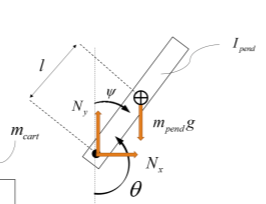

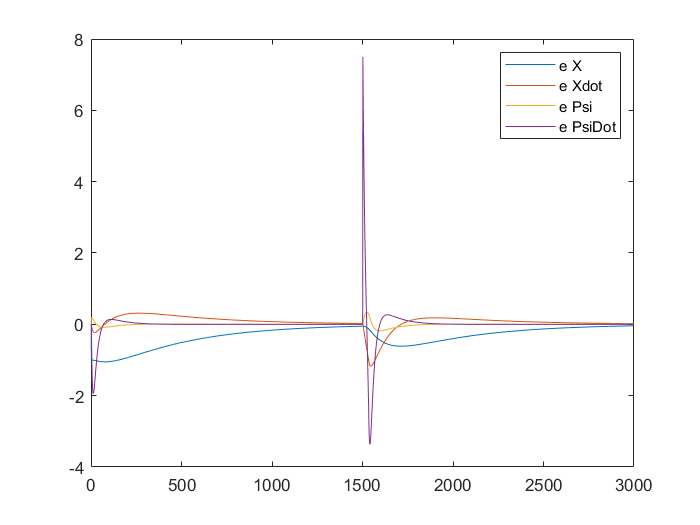

%Plot Error!!
figure(5)
plot([1:T], eTrack)
legend("e X", "e Xdot", "e Psi", "e PsiDot")

Plot LQR Baseline Case

figure(1)

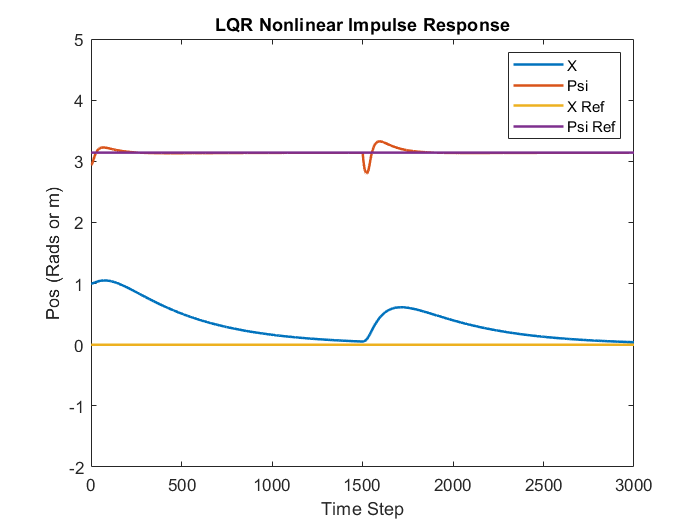

plot([1:T],XlqrAct(:,1), [1:T],XlqrAct(:,3),[1:T],lqr_ref(1,1:T), [1:T],lqr_ref(3,1:T), 'LineWidth',1.5);
ylim([-2,5]);
xlabel("Time Step");
ylabel("Pos (Rads or m)");
if nonlinear == true
    title("LQR Nonlinear Impulse Response")
else
    title("LQR Linear Impulse Response")
end
legend("X", "Psi", "X Ref", "Psi Ref")

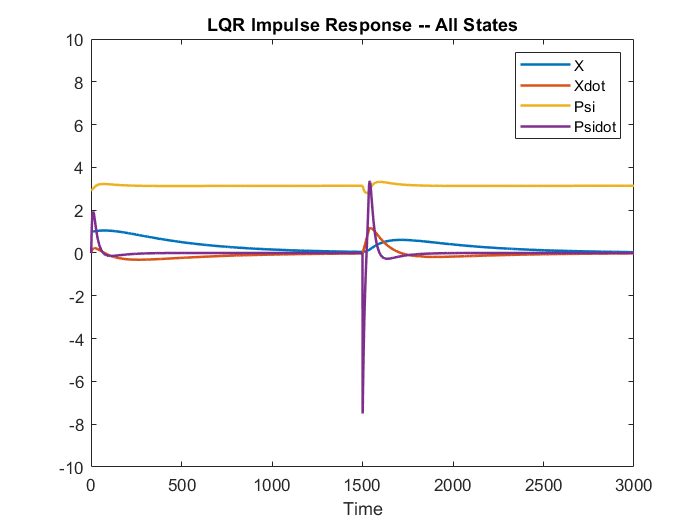

figure(4)
plot([1:T],XlqrAct(:,1), [1:T],XlqrAct(:,2),[1:T],XlqrAct(:,3), [1:T],XlqrAct(:,4), 'LineWidth',1.5);
%plot([1:T],XlqrAct(:,4), 'LineWidth', 1.5);
title("LQR Impulse Response -- All States")
legend("X", "Xdot", "Psi", "Psidot")
ylim([-10,10]);
xlabel("Time");

Plot LQR Input Force

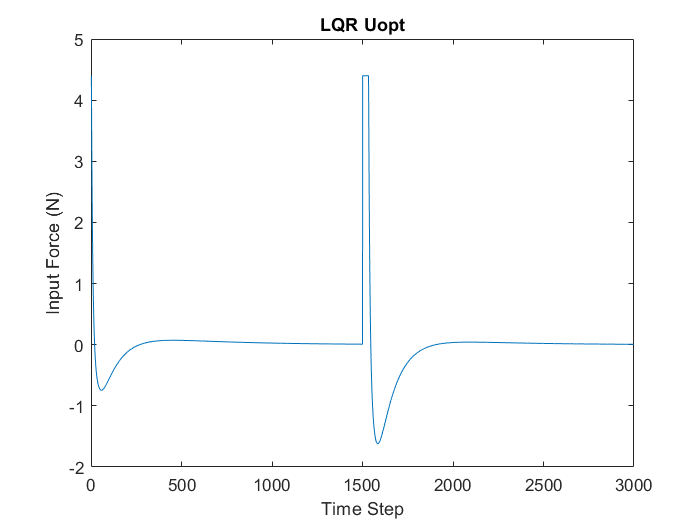

figure(2)
plot(Ulqr)
% hold on 
% plot([1:T],XlqrAct(:,2))
%ylim([-3,9]);
xlabel("Time Step");
ylabel("Input Force (N)");
title("LQR Uopt")

Plot LQR Motor Voltage

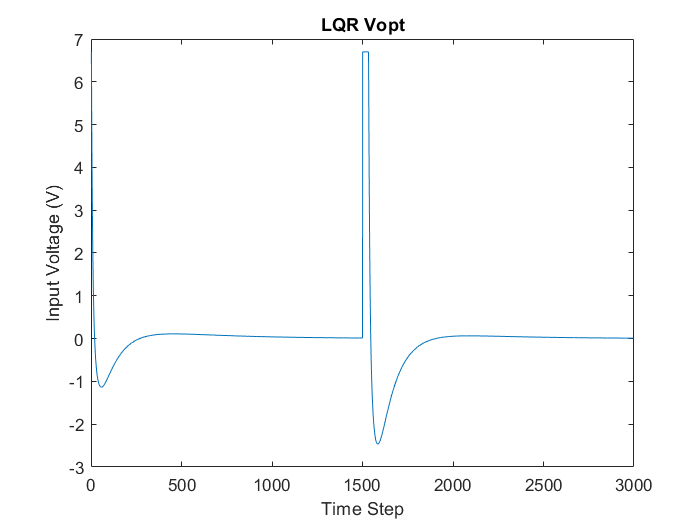

voltage_motors = Ulqr * (R_motor * r_wheel / 2 / K_T);
figure(3)
plot(voltage_motors)
%ylim([-5,13]);
xlabel("Time Step");
ylabel("Input Voltage (V)");
title("LQR Vopt")